# Define parameter

close all;
clc;
clear;


Our problem is to design an angular velocity pfofile with R and $\varphi$ ($\left.\textrm{varphi}\right)$ known. 

syms initial_x initial_y initial_theta r L initial_omegaR initial_omegaL R omegaR_max omegaL_max dt ratio varphi
initial_x = 0; % to make it easier to understand, body is placed at coordinate (0,0) worldframe
initial_y = 0;
initial_theta = pi/2; %from the picture, assume initial_theta is 90 degrees
r = 1; %from assginment 1.1
L = 2;
initial_omegaR = 0;
initial_omegaL = 0;
dt = 0.01; %sampling time

R = 100;
varphi = 2*pi/3;

according to formula:

 
$$\frac{\omega_R }{\omega_L }=\frac{2R-L}{2R\;+L}$$
 

we can decide omegaL_max  as long as the ratio is right to omegaR_max for every sa$\$mpling time, 

and because R and L already decided

ratio = (2*R-L)/(2*R+L); 
omegaL_max = 20; %decide omegaL_max
omegaR_max = omegaL_max * ratio; 

formula (11) is wrong, after Divide (10) by (8) the formula should be:


$$\varphi =\frac{r}{2L}\left({\omega_{L,\max } -\omega }_{R,\max } \right)\left(t_2 -t_1 +t_3 -t_0 \right)$$


And can be rearranged to 


$$\left(t_2 -t_1 +t_3 -t_0 \right)=\frac{2\varphi L}{r\left({\omega_{L,\;\max } -\omega }_{R,\;\max } \right)}$$



$$\left(t_2 -t_1 +t_3 \right)=\frac{2\varphi L}{r\left({\omega_{L,\;\max } -\omega }_{R,\;\max } \right)}$$


syms t0 t1 t2 t3 sum_of_time
% with t0 < t1 < t2 < t3
%from the graph, t0 = 0;
t0 = 0;

sum_of_time = (2*varphi*L) / (r*(omegaL_max-omegaR_max));
%because sum_of_time is 21.153390534171255 when executed, we configure t2, t1 to:
t2 = 10;
t1 = 5;
t3 = sum_of_time - (t2 - t1);

% test_varphi_again = r/(2*L)*(omegaR_max+omegaL_max)*sum_of_time

t1, t2, t3, t0, omegaL_max, omegaR_max already done. Next we draw the omegaL profile and omegaR profile

## OmegaL

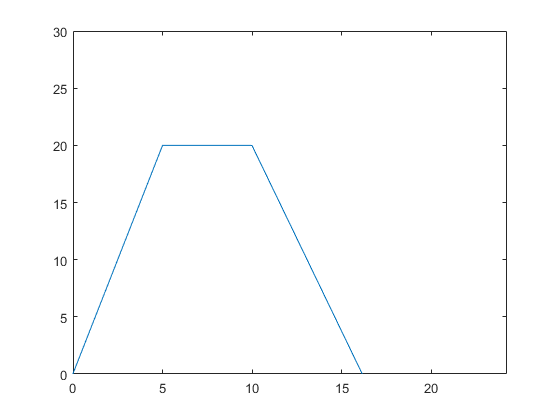

%time division
area_t_all = 0:dt:t3;
area_t0_t1 = t0:dt:t1; 
area_t1_t2 = t1:dt:t2;
area_t2_t3 = t2:dt:t3;

omegaL = zeros(1, length(area_t_all));
omegaL(1) = initial_omegaL;

for i = 2:length(area_t0_t1)
    omegaL(i) = (omegaL_max-initial_omegaL)/length(area_t0_t1)*i+ initial_omegaL;
end

%second part
for i = length(area_t0_t1):length(area_t0_t1)+length(area_t1_t2)-1
    omegaL(i) = omegaL_max;
end
% third part
for i = length(area_t0_t1)+length(area_t1_t2)-1:length(area_t_all)
    omegaL(i) = omegaL_max - ((omegaL_max)/length(area_t2_t3))*(i-(length(area_t0_t1)+length(area_t1_t2)-2));
end

plot(area_t_all, omegaL);
xlim([0 1.5*t3]);
ylim([0 1.5*omegaL_max]);

## OmegaR

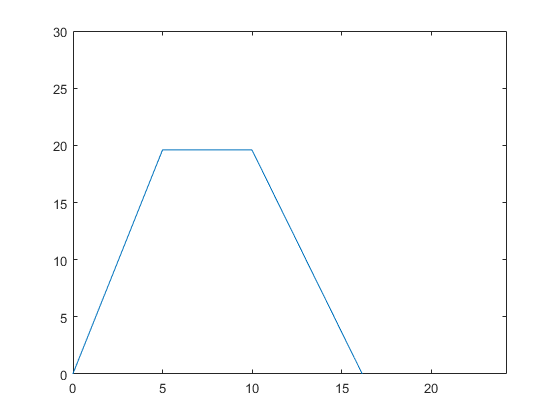

% omegaR = zeros(1, length(area_t_all));
omegaR = omegaL * ratio;
plot(area_t_all, omegaR);
xlim([0 1.5*t3]);
ylim([0 1.5*omegaL_max]);

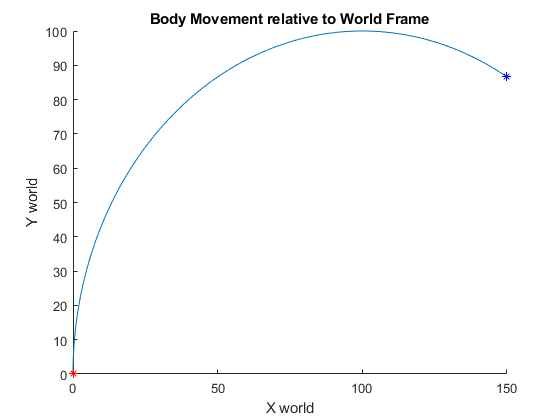

syms x_body_dot y_body_dot omega inverse_rotation_matrix x_world_dot y_world_dot xi_world_dot x_world y_world theta_array 
t_all = area_t_all;
%create arrays to hold values
x_body_dot = zeros(1, length(t_all));
y_body_dot = zeros(1, length(t_all));
omega = zeros(1, length(t_all))     ;

%assign x_body_dot values
for i = 1 : length(t_all)
    x_body_dot(i) = r*omegaR(i)/2 + r*omegaL(i)/2;
end
%we dont need to assign y_body_dot because it's always zero (already zero
%in initialization)

%assign omega values
for i = 1 : length(t_all)
%     omega(i) = (r*omegaR(i)/L) - (r*omegaL(i)/L);
    omega(i) = (r/L)*(omegaR(i)-omegaL(i));
end

xi_body_dot = [x_body_dot; y_body_dot; omega];

%before we put inverse_rotation_matrix, we need to make an array of theta,
%because theta for every sampling time is different due to omegaR != omegaL
theta_array = zeros(1, length(t_all));
theta_array(1) = initial_theta;


%because we already got omega for every sampling time, we can assign theta
%value by integrate it 
for i = 2 : length(t_all)
    theta_array(i) = theta_array(i-1) + (omega(i)+omega(i-1))*dt/2;
end

% plot(t_all, theta_array);
%inverse_rotation_matrix
%because theta for every sampling time is different, so does the
%inverse_rotation_matrix

%initialize 3 dimensional matrix to store inverse_rotation_matrix
inverse_rotation_matrix = zeros(3, 3 ,length(t_all));
%put initial value
inverse_rotation_matrix(:,:,1) = [cos(initial_theta) -sin(initial_theta) 0; sin(initial_theta) cos(initial_theta) 0; 0 0 1];
%update theta for every sampling time
for i = 2 : length(t_all)
    inverse_rotation_matrix(:,:,i) = [cos(theta_array(i)) -sin(theta_array(i)) 0; sin(theta_array(i)) cos(theta_array(i)) 0; 0 0 1];
end

%initialize xi_world_dot array
xi_world_dot = zeros(3, length(t_all));

%xi_world_dot = inverse_rotation_matrix*xi_body_dot
for i= 1 : length(t_all)
    xi_world_dot(:,i) = inverse_rotation_matrix(:,:,i)* xi_body_dot(:,i);
end

%init x_world dot and y_world_dot
x_world_dot = zeros(1, length(t_all));
y_world_dot = zeros(1, length(t_all));

%assign value
for i = 1 : length(t_all)
    x_world_dot(i) = xi_world_dot(1,i);
    y_world_dot(i) = xi_world_dot(2,i);
end

%init x_world and y_world
x_world = zeros(1, length(t_all));
y_world = zeros(1, length(t_all));

% assign initial position, we dont need to assign theta, because it is
% already assigned in array theta_array

x_world(1) = initial_x;
y_world(1) = initial_y;

for i = 2: length(t_all)
    x_world(i) = x_world(i-1) + (x_world_dot(i)+x_world_dot(i-1))*dt/2;
    y_world(i) = y_world(i-1) + (y_world_dot(i)+y_world_dot(i-1))*dt/2;
end

% plot(x_world, y_world);
%plotting
plot3(x_world, y_world, theta_array)
xlabel("X world");
ylabel("Y world");
zlabel("Theta");
title('Body Movement relative to World Frame')

%set view to this value, so we can see the graph from up
% i dont know how to put theta information in 2D plot :(
view([0.0 90.00])

%put symbol to initial and final value
hold on
plot3(x_world(1),y_world(1), theta_array(1), 'r*'); %red star for initial value
plot3(x_world(length(t_all)), y_world(length(t_all)), theta_array(length(t_all)), 'b*'); % blue star for final value